%Track generale
%Necessario matlab mobile -> raccogliere data da applicazione matlab
%QUanti passi, velocita, 

%log campo magnetico
clear

m = mobiledev

m = mobiledev with properties:

                      Device: 'Galaxy Note9'
                   Connected: 1
                     Logging: 0
            AvailableCameras: {'back' 'front'}
            InitialTimestamp: ''

   AccelerationSensorEnabled: 0
AngularVelocitySensorEnabled: 0
       MagneticSensorEnabled: 1
    OrientationSensorEnabled: 0
       PositionSensorEnabled: 0
Show all properties

m.Logging = 1

m = mobiledev with properties:

                      Device: 'Galaxy Note9'
                   Connected: 1
                     Logging: 1
            AvailableCameras: {'back' 'front'}
            InitialTimestamp: ''

   AccelerationSensorEnabled: 0
AngularVelocitySensorEnabled: 0
       MagneticSensorEnabled: 1
    OrientationSensorEnabled: 0
       PositionSensorEnabled: 0

Current Sensor Values:
               MagneticField: [0x3 double] (Waiting for data)
Show all properties

disp(m)

mobiledev with properties:

                      Device: 'Galaxy Note9'
                   Connected: 1
                     Logging: 1
            AvailableCameras: {'back' 'front'}
            InitialTimestamp: ''

   AccelerationSensorEnabled: 0
AngularVelocitySensorEnabled: 0
       MagneticSensorEnabled: 1
    OrientationSensorEnabled: 0
       PositionSensorEnabled: 0

Current Sensor Values:
               MagneticField: [0x3 double] (Waiting for data)
Show all properties


waitforbuttonpress
m.Logging = 0

m = mobiledev with properties:

                      Device: 'Galaxy Note9'
                   Connected: 1
                     Logging: 0
            AvailableCameras: {'back' 'front'}
            InitialTimestamp: '27-May-2023 12:24:51.813'

   AccelerationSensorEnabled: 0
AngularVelocitySensorEnabled: 0
       MagneticSensorEnabled: 1    (27 Logged values)
    OrientationSensorEnabled: 0
       PositionSensorEnabled: 0
Show all properties

[mf, t] = magfieldlog(m)

mf =           16.1999988555908          6.23999977111816         -41.0999984741211
          16.6199989318848          5.51999998092651         -41.1599998474121
          17.4599990844727          5.51999998092651         -40.9799995422363
          17.2199993133545          4.92000007629395          -40.439998626709
          17.3400001525879          4.19999980926514          -40.379997253418
          17.3999996185303           4.1399998664856          -40.439998626709
          16.6199989318848          4.55999994277954         -40.6199989318848
          17.1599998474121                       4.5         -40.7999992370605
          17.0399990081787                       4.5         -40.9199981689453
          16.7399997711182          4.55999994277954         -40.3199996948242


t =                          0
         0.100000143051147
         0.200000047683716
         0.299999952316284
         0.400000095367432
                       0.5
         0.600000143051147
         0.700000047683716
         0.799999952316284
         0.900000095367432


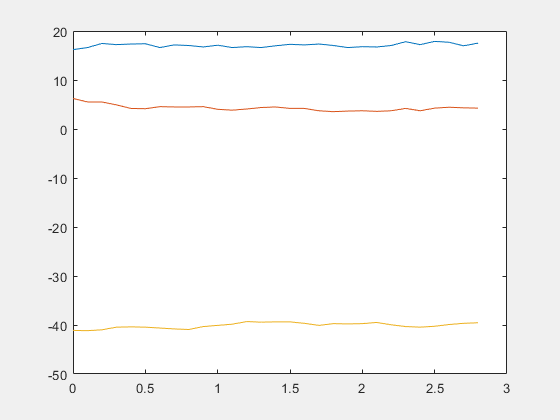


plot(t,mf)


%RILEVAMENTO POSIZIONE CAMPO MAGNETICO
%usare la triangolazione del campo magnetico per determinare la posizione
%approssimata
%punti di forza: rilevamento di posizione in assenza di GPS


%calcolo della data
format longG
t = now

t =           739033.517344433


date = datetime(t,'ConvertFrom','datenum')

date = datetime
   27-May-2023 12:24:58



[XYZ, H, D, I, F] = wrldmagm(120,39.082520,-94.582306,decyear(date))

XYZ =           20624.6756554183
          448.130242047354
          47479.9102177231


H =           20629.5435384558


D =           1.24471931438566


I =           66.5155383874581


F =            51767.943178072



height=120;

%finding of the position
for longitude = [-180:3.6:180]
    for latitude = [-90:3.6:90]
        [XYZ] = wrldmagm(height,latitude,longitude,decyear(date));

    end
end
